% Clear previous ROS instances and initialize a new one
rosshutdown();

Shutting down global node /matlab_global_node_15274 with NodeURI http://192.168.178.112:52102/ and MasterURI http://192.168.178.125:11311.


setenv('ROS_MASTER_URI', 'http://192.168.178.125:11311');
setenv('ROS_IP', '192.168.178.112');  
rosinit('192.168.178.125');

The value of the ROS_IP environment variable, 192.168.178.112, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_66665 with NodeURI http://192.168.178.112:52469/ and MasterURI http://192.168.178.125:11311.


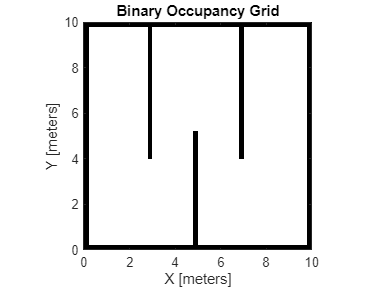


% Create a map for your robot
myMap = binaryOccupancyMap(10, 10, 5);
walls = zeros(50,50);
walls(1,:) = 1;
walls(:,1) = 1;
walls(end,:) = 1;
walls(:,end) = 1;
walls(1:30,15) = 1;
walls(25:end,25) = 1;
walls(1:30,35) = 1;
setOccupancy(myMap,[1,1],walls,'grid');
show(myMap);

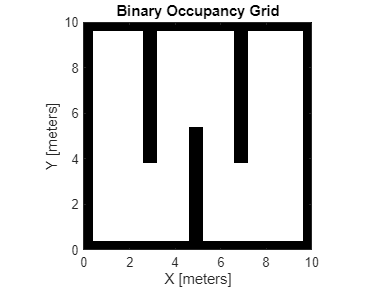

inflateRadius = 0.2;
inflate(myMap,inflateRadius);
show(myMap);

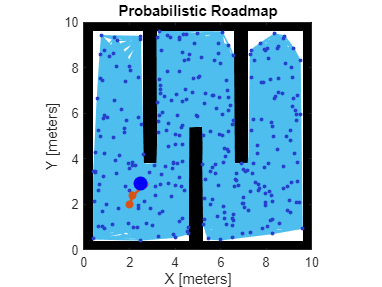


% Set up the path planning using PRM
prm = robotics.PRM(myMap);
prm.NumNodes = 300;
figure;
show(prm,'Parent', axes);

start = [2 2];
stop = [2.5 3];
path = findpath(prm, start, stop);
hold('on');
show(prm, 'Map', 'on','Roadmap', 'on');

% Robot and controller initialization
initialOrientation = 0;
controller = robotics.PurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.04;  % Set constant linear velocity here
controller.MaxAngularVelocity = 0.3;
controller.LookaheadDistance = 0.6;

% Robot model (differential drive)
trackWidth = 0.4;
wheelRadius = 0.125;
robot = differentialDriveKinematics("TrackWidth", trackWidth, "WheelRadius",wheelRadius);

% Visualization
robotCurrentLocation = path(1,:);
robotGoal = path(end,:);
robotPlot = plot(robotCurrentLocation(1), robotCurrentLocation(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');

% Define robot starting point
startPoint = [robotCurrentLocation initialOrientation]';

% Goal radius and parameters for the controller
goalRadius = 0.1;
distanceToGoal = norm(robotCurrentLocation - robotGoal);
sampleTime = 0.1;

% Initialize ROS publisher for velocity messages
velocityPublisher = rospublisher('/cmd_vel_array', 'std_msgs/Float32MultiArray');

% Main control loop
while distanceToGoal > goalRadius
    % Compute control commands (linear and angular velocities)
    [v, omega] = controller(startPoint);  % Pass the (x, y) part of startPoint

    % Create a ROS message for publishing linear and angular velocities
    velocityMsg = rosmessage('std_msgs/Float32MultiArray');
    velocityMsg.Data = [v, omega];  % Assign linear.x and angular.z

    % Publish the message
    send(velocityPublisher, velocityMsg);

    % Display the values for debugging
    %disp(['Published Linear Velocity: ', num2str(v)]);
    %disp(['Published Angular Velocity: ', num2str(omega)]);

    % Update the robot's velocity and pose
    vel = derivative(robot, startPoint, [v omega]);

    % Update the robot's position based on the velocities
    startPoint = startPoint + vel * sampleTime;

    % Update the distance to the goal
    distanceToGoal = norm(startPoint(1:2) - robotGoal(:));

    % Update the robot's plot position on the map
    set(robotPlot, 'XData', startPoint(1), 'YData', startPoint(2));

    % Pause to allow visualization
    pause(0.1);
end


% Stop the robot after reaching the goal
velocityMsg.Data = [0, 0];  % Stop the robot by setting velocities to zero
send(velocityPublisher, velocityMsg);
disp('Goal reached. Robot stopped.');

Goal reached. Robot stopped.



% Shutdown the ROS node after execution
rosshutdown();

Shutting down global node /matlab_global_node_66665 with NodeURI http://192.168.178.112:52469/ and MasterURI http://192.168.178.125:11311.
